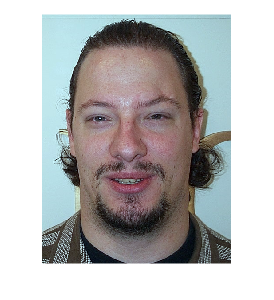


img255 = (imread('..\DB1/db1_05.jpg'));
img255 = colorCorrection(img255);
img = im2double(img255);
imshow(img)

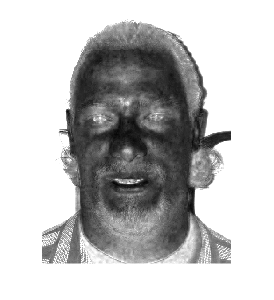


imgChrome = rgb2ycbcr(img);
%uint64(255 * mat2gray(grayImage))
Y = uint16(255 * mat2gray(imgChrome(:,:,1)));
Cb = uint16(255 * mat2gray(imgChrome(:,:,2)));
Cr = uint16(255 * mat2gray(imgChrome(:,:,3)));

Cr_neg = 255 - Cr;

EyeMapC = (1/3).*(Cb.^2 + Cr_neg.^2 + (Cb./Cr));

EyeMapC = im2double(EyeMapC);

imshow(EyeMapC, []) %Show 

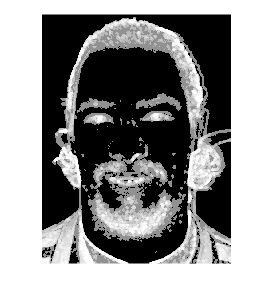


se = strel('disk', 4);

EyeMapL = imdilate(Y, se) ./ (imerode(Y, se) + 1);

EyeMapL = im2double(histeq(EyeMapL));

imshow(EyeMapL, [])

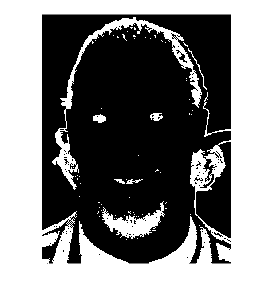


EyeMap = EyeMapL.*EyeMapC;

EyeMap = histeq(EyeMap);

EyeMap = EyeMap > 0.85;

imshow(EyeMap,[])

## Mouthmask

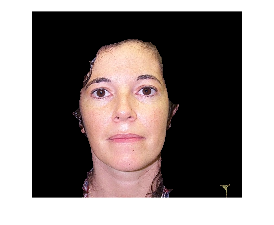


img = imread('..\DB1/db1_12.jpg');
faceMask = generateFaceMask(img);
img = im2double(img);
img = img.*faceMask;

number_of_pixels = sum(faceMask(:));

imshow(img)

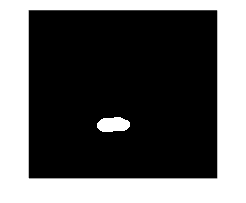


imgChrome = rgb2ycbcr(img);
Y = mat2gray(imgChrome(:,:,1)) + 1;
Cb = mat2gray(imgChrome(:,:,2)) + 1;
Cr = mat2gray(imgChrome(:,:,3)) + 1;

mean_Cr_squared = sum(Cr(:).^2)./number_of_pixels;

mean_Cr_by_Cb = (sum(Cr(:)./sum(Cb(:))))./number_of_pixels;

My = 0.95*mean(Cr(:).^2)./(mean(Cr(:)./Cb(:)));

MouthMap = (Cr.^2).*((Cr.^2) - My*(Cr./Cb)).^2;
MouthMap = (MouthMap- min(MouthMap(:)))/(max(MouthMap(:)) - min(MouthMap(:)));

se1 = strel('disk', 12);


MouthMap = MouthMap > 0.2;

MouthMap = bwareaopen(MouthMap, 200);
MouthMap = imdilate(MouthMap, se1);


imshow(MouthMap)

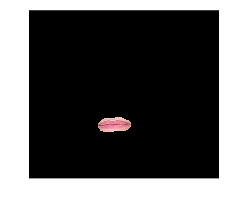

alfa2 = 1

beta2 = 1

alpha = 0.6389

beta = 1.2398

eyePos =   385.8636  285.7094
  528.7027  290.0000


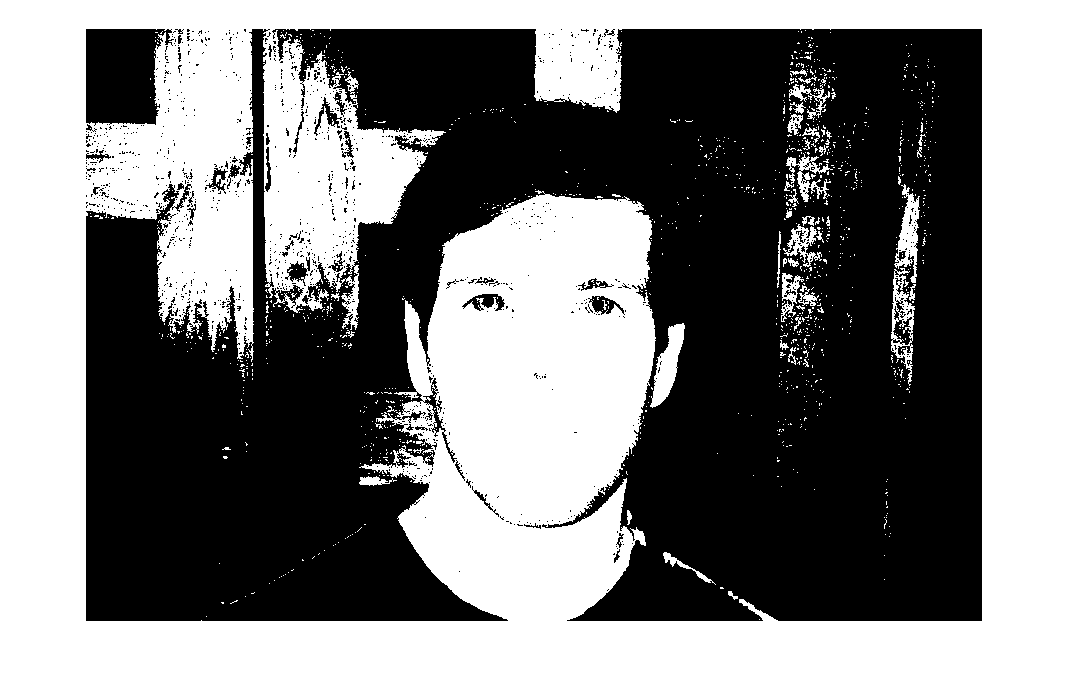


banan = img.*MouthMap;

imshow(banan)